# Q2 of assignment.

Defining the signals

n = 0:1:20;

x = u(n-1) - u(n-6);
h2 = u(n-1) - u(n-2);
sig_2 = h1(n);

x1 = conv(x,h1(n));
y = conv(x1,h2);

Plotting the signals now.

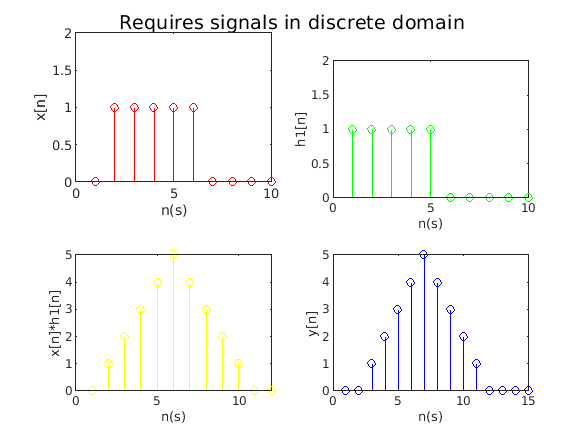

subplot(2,2,1), stem(x,'r'), ylabel('x[n]'), xlabel('n(s)'), axis([0 10 0 2]);

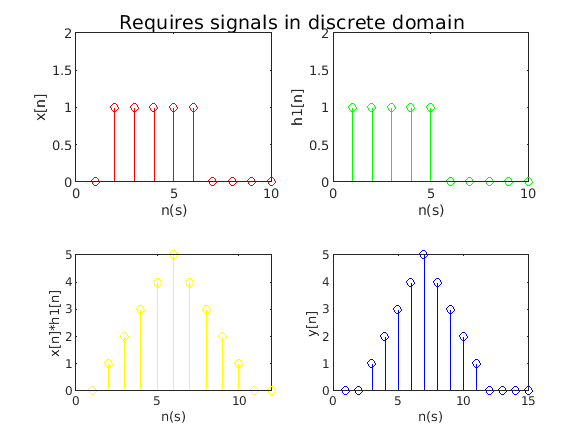

subplot(2,2,2), stem(sig_2,'g'), ylabel('h1[n]'), xlabel('n(s)'), axis([0 10 0 2]);

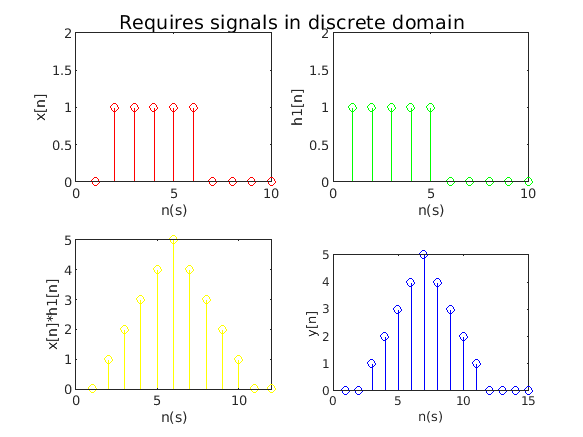

subplot(2,2,3), stem(x1,'y'), ylabel('x[n]*h1[n]'), xlabel('n(s)'), axis([0 12 0 5]);

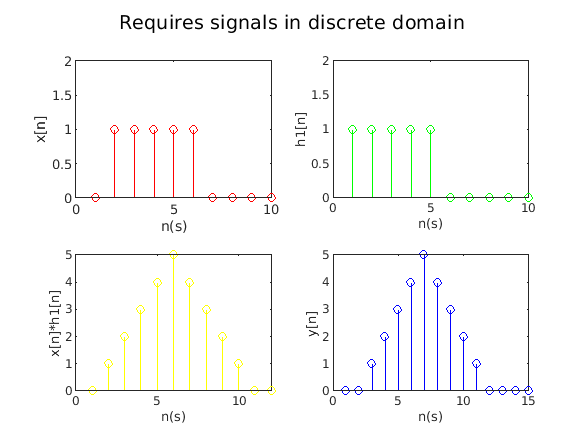

subplot(2,2,4), stem(y,'b'), ylabel('y[n]'), xlabel('n(s)'),axis([0 15 0 5]);
suptitle('Requires signals in discrete domain');